dirs = CleanDir('C:\Users\John\Desktop\Instru\ProcessedData_Stim_bbcorr\Analysis\Extra\Corr\Magnitude_regress')

dirs = 1×21 cell array
    {'Instru_EEG_001'}    {'Instru_EEG_003INT'}    {'Instru_EEG_004'}    {'Instru_EEG_005'}    {'Instru_EEG_006INT'}    {'Instru_EEG_007INT'}    {'Instru_EEG_008INT'}    {'Instru_EEG_009INT'}    {'Instru_EEG_011INT'}    {'Instru_EEG_013INT'}    {'Instru_EEG_014INT'}    {'Instru_EEG_015INT'}    {'Instru_EEG_017'}    {'Instru_EEG_018'}    {'Instru_EEG_026'}    {'Instru_EEG_032'}    {'Instru_EEG_063'}    {'Instru_EEG_079'}    {'Instru_EEG_1001INT'}    {'Instru_EEG_1002INT'}    {'Instru_EEG_114'}


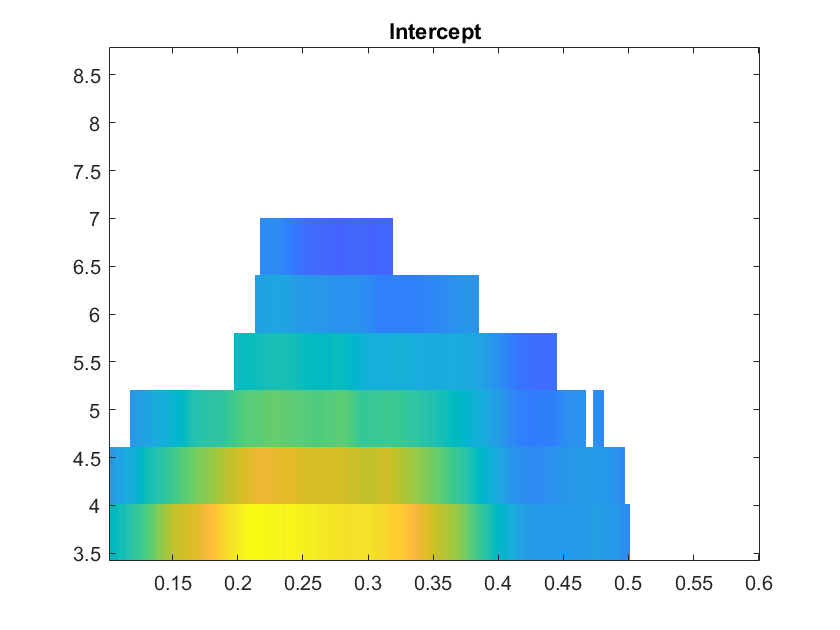

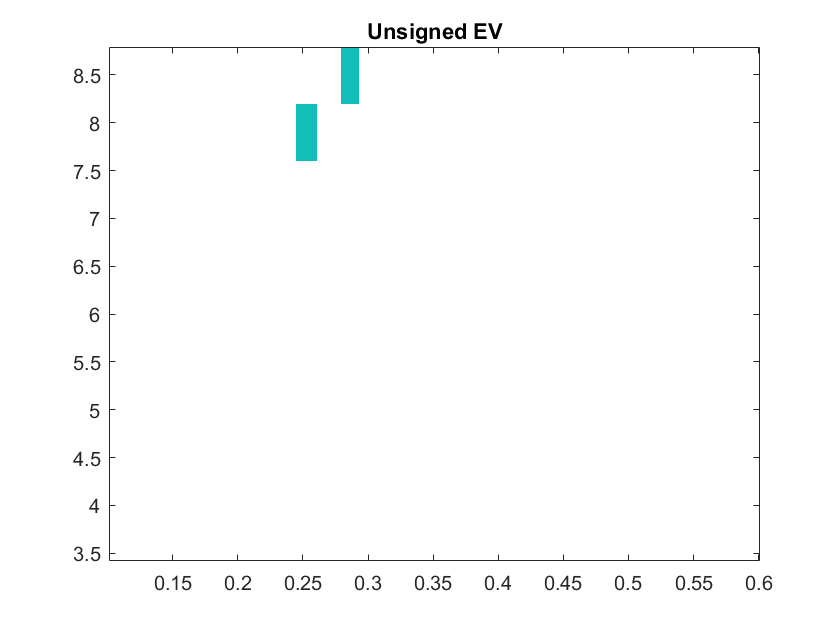

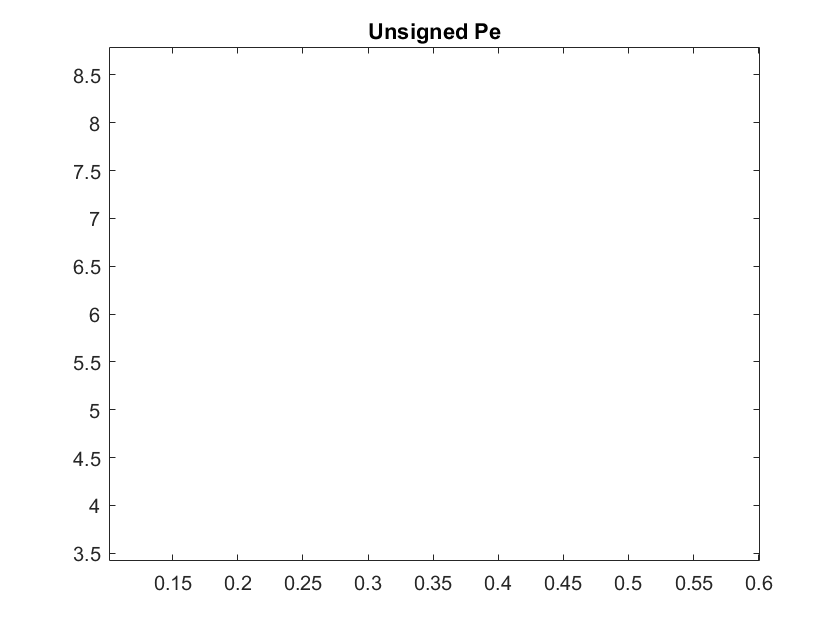

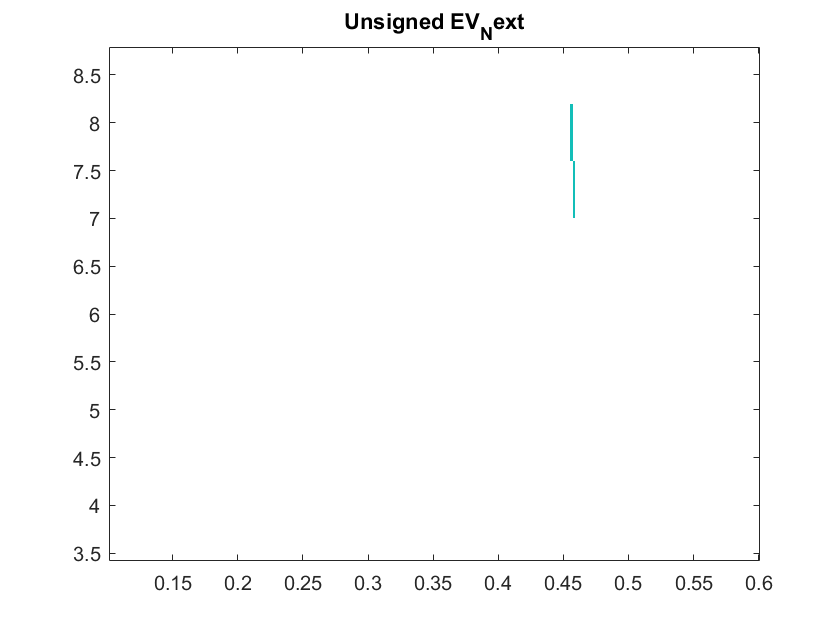

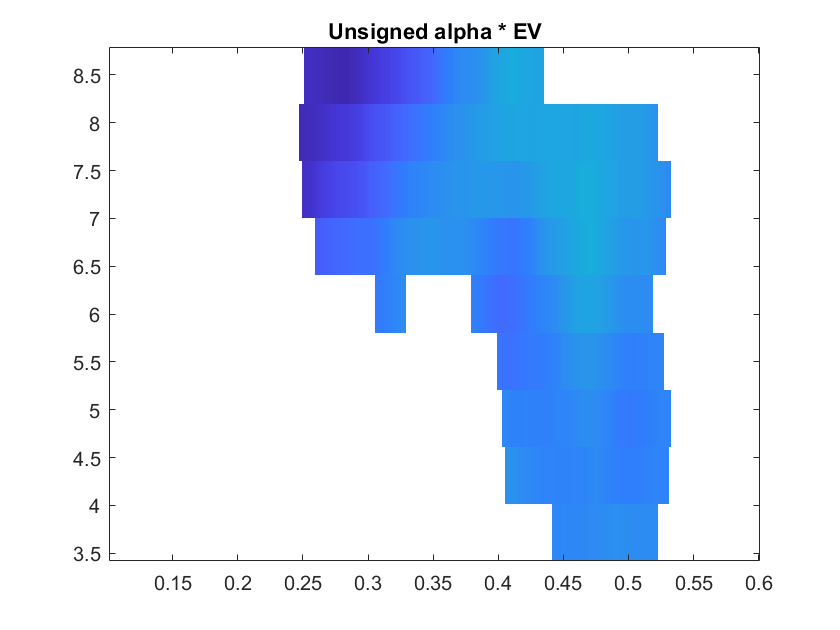

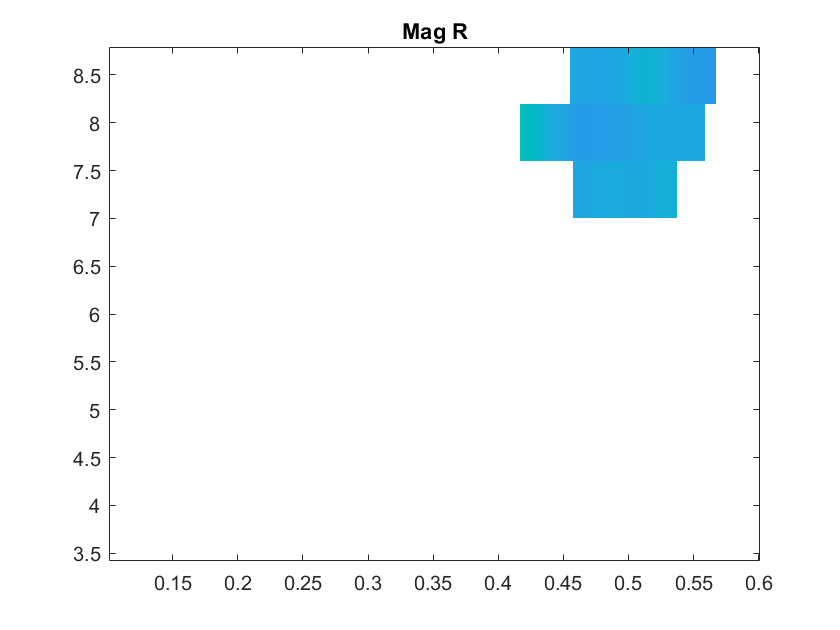

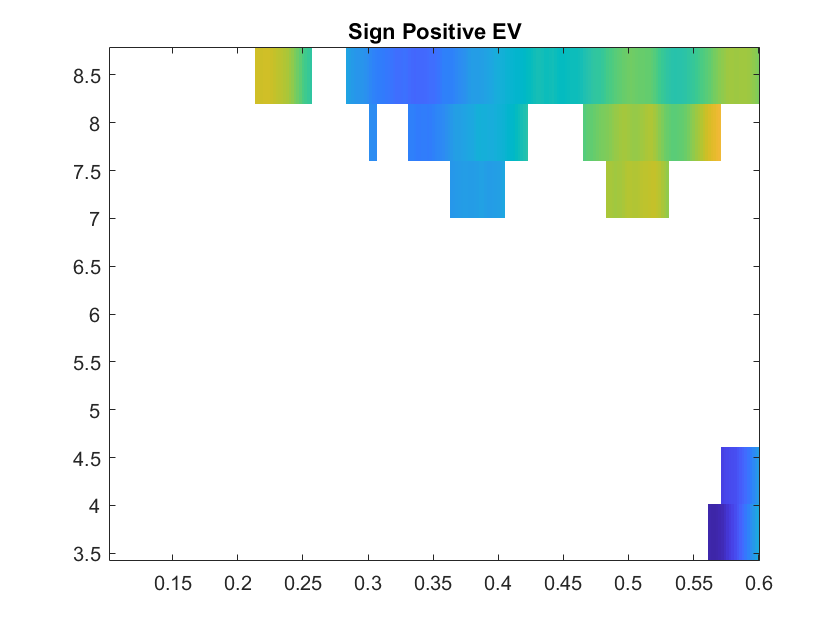

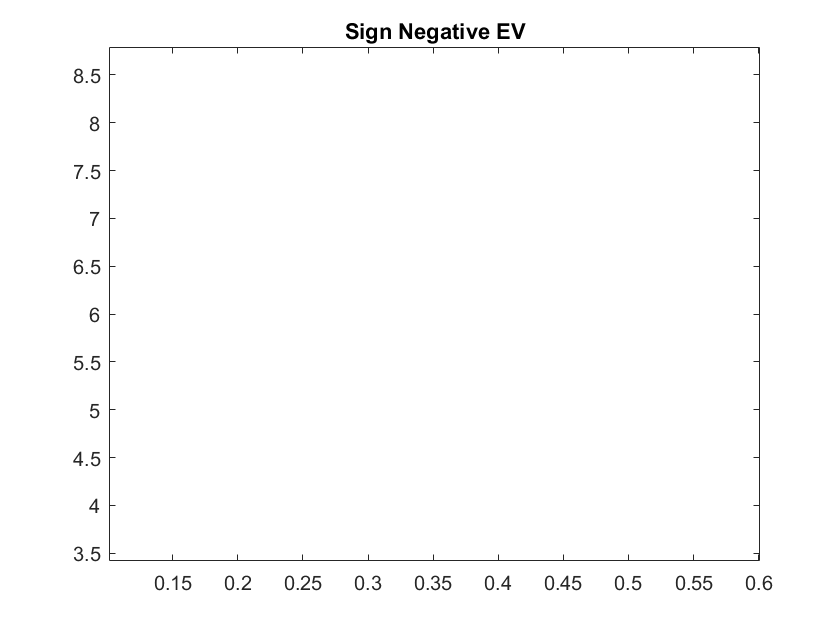


for dir = 1:length(dirs)

dat = load(['C:\Users\John\Desktop\Instru\ProcessedData_Stim_bbcorr\Analysis\Extra\Corr\Magnitude_regress\' dirs{dir} '\Fdb Onset\All\FCz.mat']);

spctrm(:,:,:,:,dir) = dat.R.powspctrm;

freqz = dat.R.freq;
timez = dat.R.time;
end

titles = {'Intercept','Unsigned EV','Unsigned Pe', 'Unsigned EV_Next', 'Unsigned alpha * EV' 'Mag R',...
         'Sign Positive EV' 'Sign Negative EV', 'Sign Positive Pe' 'Sign Negative Pe', ...
         'Sign Positive EV_next' 'Sign Negative EV_next', 'Sign Positive alpha * EV' 'Sign Negative alpha * EV', ...
         'Sign Positive R' 'Sign Negative R',...
         'Signed Positive EV' 'Signed Negative EV', 'Signed Positive Pe' 'Signed Negative Pe', ...
         'Signed Positive EV_next' 'Signed Negative EV_next', 'Signed Positive alpha * EV' 'Signed Negative alpha * EV', ...
         'Signed Positive R' 'Signed Negative R'};

for spct=1:size(spctrm,4)


 stat = [];
for freq = 1:size(spctrm,2)

    bsl = nanmean(spctrm(:,freq,timez > -.2 & timez <0,spct,:),3);

    for time = 1:size(spctrm,3)

       [H,P,CI,STATS] = ttest(bsl,spctrm(:,freq,time,spct,:));

        stat(freq,time) = P;

    end
end

%stat = fdr(stat,.01);

d = figure;
dat = squeeze(nanmean(spctrm(:,freqz>3.5 & freqz<8.5,timez>.1 & timez<.6,spct,:),5));
a = imagesc(timez(timez>.1 & timez<.6),freqz(freqz>3.5 & freqz<8.5),dat);
a.AlphaData = stat(freqz>3.5 & freqz<8.5,timez>.1 & timez<.6) < .05;
set(gca,'YDir','normal');
set(d,'Visible',true)
title(titles{spct});

nanmean(nanmean(spctrm(:,freqz>3.5 & freqz<8.5,timez>.1 & timez<.6,spct,:),[3]),2)

end